% Andrew Hutsell
% MATH 515
% Problem Set 3

% Exercise 3

% Part a - Neville's Table
clear; clc; close all;

% Problem Inputs
x = [0 1 2];
y = [2 -1 4];
xbar = 1.3;

% Determine the size of matrix Neville_Table
n = length(x);
% Initialize matrix
Neville_Table = zeros(n, n);
    
% Initialize table
for i = 1:n
    Neville_Table(i,1) = y(i);
end
    
% Fill the table
for j = 2:n
    for i = 1:n-j+1
        Neville_Table(i,j) = ((xbar - x(i)) * Neville_Table(i+1,j-1) - ...
                  (xbar - x(i+j-1)) * Neville_Table(i,j-1)) /(x(i+j-1) - x(i));
    end
end
    
% Final approximated value
Neville_Table

Neville_Table =     2.0000   -1.9000   -0.3400
   -1.0000    0.5000         0
    4.0000         0         0





% Part b - Newton's Divided Difference Table 

% Uses the same inputs at Neville's Table Code
n = length(x);

% Initialize table
Newton_Div_Diff = zeros(n,n);
for i = 1:n
    Newton_Div_Diff(i,1) = y(i);
end

% Fill the table
for j = 2:n
    for i = 1:n-j+1
        Newton_Div_Diff(i,j) = (Newton_Div_Diff(i+1,j-1) - Newton_Div_Diff(i,j-1)) / (x(i+j-1) - x(i));
    end
end

% Display table
Newton_Div_Diff

Newton_Div_Diff =      2    -3     4
    -1     5     0
     4     0     0



% Approximate Value at \bar{x} = 1.3
Interp_Value = Newton_Div_Diff(1,1);
product = 1;

for j = 2:n
    product = product * (xbar - x(j-1));
    Interp_Value = Interp_Value + Newton_Div_Diff(1,j) * product;
end

% Final approximated value
Interp_Value

Interp_Value = -0.3400

clear; clc; close all;
% Exercise 4

% Function
f = @(x) x .* exp(-x);

% Interval
a = -1; 
b = 3;

% Degree
n = 4;

% Dense grid
x = linspace(a,b,10000);
fx = f(x);

% Uniformly Spaces Points

x_a = linspace(a,b,n+1);
y_a = f(x_a);

p_a = polyfit(x_a, y_a, n);
p_a_vals = polyval(p_a, x);

err_a = abs(fx - p_a_vals);
Linf_a = max(err_a);
L2_a = sqrt(trapz(x, err_a.^2)/(b-a));


% Scaled and Translated Chebyshev Points

i = 0:n;
t_b = cos((2*i+1)*pi/(2*(n+1)));

x_b = (a+b)/2 + (b-a)/2 * t_b;

y_b = f(x_b);

p_b = polyfit(x_b, y_b, n);
p_b_vals = polyval(p_b, x);

err_b = abs(fx - p_b_vals);
Linf_b = max(err_b);
L2_b = sqrt(trapz(x, err_b.^2)/(b-a));


% Scaled and Translated Legendre Points

% Hard coded roots that were determined by hand
t_c = [-0.9061798459;
         -0.5384693101;
          0;
          0.5384693101;
          0.9061798459];

x_c = (a+b)/2 + (b-a)/2 * t_c;
y_c = f(x_c);

p_c = polyfit(x_c, y_c, n);
p_c_vals = polyval(p_c, x);

err_c = abs(fx - p_c_vals);
Linf_c = max(err_c);
L2_c = sqrt(trapz(x, err_c.^2)/(b-a));


% Results

fprintf('Uniform nodes:');

Uniform nodes:

Linf_a, L2_a

Linf_a = 0.0767

L2_a = 0.0316


fprintf('Chebyshev nodes:');

Chebyshev nodes:

Linf_b, L2_b

Linf_b = 0.0461

L2_b = 0.0221


fprintf('Legendre nodes:');

Legendre nodes:

Linf_c, L2_c

Linf_c = 0.0921

L2_c = 0.0196

clear; clc; close all;
% Exercise 5

function c = finite_diff_coeffs(n, dx)
    k = length(dx);
    
    % Build matrix
    A = zeros(k, k);
    for m = 0:k-1
        A(m+1, :) = dx.^m;
    end
    
    % RHS vector
    b = zeros(k,1);
    b(n+1) = factorial(n);
    
    % Solve system
    c = A \ b;
end

% Part a
h = 1;
% Forward First Derivative
dx = [0, h];
c = finite_diff_coeffs(1, dx)

c =     -1
     1



% Centered First Derivative
dx = [-h, h];
c = finite_diff_coeffs(1, dx)

c =    -0.5000
    0.5000



% Centered Second Derivative
dx = [-h, 0, h];
c = finite_diff_coeffs(2, dx)

c =      1
    -2
     1




% Part b
f = @(x) exp(x);
true_val = 1; % derivative at x=0

hs = 2.^(-(2:10));
errors = zeros(size(hs));

for i = 1:length(hs)
    h = hs(i);
    dx = [-h, h];
    c = finite_diff_coeffs(1, dx);
    
    approx = c(1)*f(-h) + c(2)*f(h);
    errors(i) = abs(approx - true_val);
end
c

c =   -512
   512


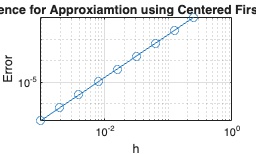

loglog(hs, errors, 'o-')
grid on
xlabel('h')
ylabel('Error')
title('Convergence for Approxiamtion using Centered First Derivative')

p = polyfit(log(hs), log(errors), 1);
p(1)

ans = 2.0004


% Part c
f = @(x) sin(x);
true_val = 1; % derivative at x=0

hs = 2.^(-(2:10));
errors = zeros(size(hs));

for i = 1:length(hs)
    h = hs(i);
    dx = [0, h, 2*h, 3*h, 4*h];
    c = finite_diff_coeffs(1, dx);
    
    approx = sum(c .* f(dx(:)));
    errors(i) = abs(approx - true_val);
end

c

c = 1.0e+03 *

   -2.1333
    4.0960
   -3.0720
    1.3653
   -0.2560


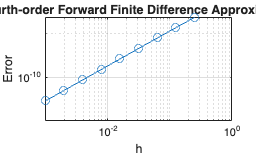

loglog(hs, errors, 'o-')
grid on
xlabel('h')
ylabel('Error')
title('Fourth-order Forward Finite Difference Approximation')


p = polyfit(log(hs), log(errors), 1);
p(1)

ans = 3.9883